# 7주차 — 보상기 설계: 궤적을 옮기기

**제어시스템설계** · 충남대학교 자율운항시스템공학과

**참고자료 — 먼저 볼 것**

아래 다섯 과목은 **이 강의의 담당교수가 직접 한 강의**입니다. 기초부터 대학원 과정까지 이어지므로 부족한 곳부터 보면 됩니다. 이 강의에서 쓰는 기호와 유도는 모두 그 안에서 자세히 다룹니다.

**MATLAB 이나 Simulink 가 아직 익숙하지 않다면** 실습에 들어가기 전에 아래를 먼저 하십시오. 무료이고 각각 몇 시간이면 끝납니다.

6주차에서 벽에 부딪혔습니다.

- "오버슈트 $20\%$, 정착시간 $2$ 초" 를 비례제어로는 만족할 수 없다

- 궤적이 사양 영역을 지나지 않기 때문이다

오늘 그 문제를 풉니다. 방법은 하나입니다 — **궤적 자체를 옮긴다.**

오늘 배울 것

- **설계 6단계** — 사양에서 제어기까지 가는 정해진 길

- **PD** — 영점을 추가해 궤적을 왼쪽으로

- **PI** — 원점 극점을 추가해 정상상태 오차를 없앰

- **Lead** — PD 를 실제로 만들 수 있게 고친 것

- **Lag** — PI 를 안전하게 고친 것

- **제어입력 사양** — 구동기 한계를 처음부터 설계에 넣기

if isempty(which('plant_msd'))   % 경로가 아직 등록 안 되었으면 알아서 잡는다
    p_ = pwd;
    if ~isempty(mfilename('fullpath')), p_ = fileparts(mfilename('fullpath')); end
    for k_ = 1:4
        if isfile(fullfile(p_,'setup_path.m')), run(fullfile(p_,'setup_path.m')); break; end
        p_ = fileparts(p_);
    end
    clear p_ k_
end
clc; close all;
s = tf('s');

## 0-0. 오늘 돌려 볼 파일

오늘은 파일이 많습니다. **어느 절에서 어느 파일을 여는지**를 표로 정리했습니다. 모두 `W07_RootLocus_Design` 폴더 안에 있습니다.

도우미 함수 두 개도 오늘 처음 씁니다. 둘 다 `common/` 에 있습니다.

실행하는 법 — 파일을 열고 절 안에서 `Ctrl+Enter` 를 누르면 그 절만 돕니다. 전체는 `F5` 입니다. 처음 한 번은 `setup_path` 를 먼저 실행하십시오.

## 0-0-1. 이번 주는 순서를 정해 두고 읽으십시오

7주차는 이번 학기에서 **파일이 가장 많은 주**입니다. 다음 주가 중간고사이므로, 한 번에 다 보려 하지 말고 아래 순서를 지키십시오.

**시간이 부족하면** 1~4 단계까지만 하십시오. 그 넷이 중간고사 범위의 핵심이고, 5·6 단계는 그 위에 얹는 확장입니다.

**시험 대비로 다시 볼 때**는 각 스크립트의 마지막 절 (`이번 실습의 정리`) 만 이어서 읽으면 한 주 분량이 15 분에 복습됩니다.

이 강의노트의 **그림은 전부** `make_figures.m` 이 만들어 `common/figures/` 에 넣어 둔 것입니다. 그림마다 어느 함수가 만들었는지 아래에 적어 두었습니다.

## 0. 오늘 한 장 요약

6주차의 결론은 이것이었습니다.

- **비례이득은 길 위에서 점을 옮길 뿐, 길 자체는 못 바꾼다**

그러니 길이 사양 영역을 비껴가면 손을 쓸 수 없습니다. 오늘은 **길 자체를 옮기는 법**을 배웁니다. 방법은 하나입니다.


$$\text{제어기에 극점이나 영점을 더한다}$$


오늘의 계단

- **1-1절** 근궤적 설계 6단계 (오늘부터 모든 설계는 이 순서로)

- **1-2절** 새 도구 두 개 (`rl_scan`, `ctrl_input`)

- **1-3절** 비례제어 설계 세 문제 — 되는 것 하나, 안 되는 것 둘

- **2~4절** PD 와 PI. 무엇을 언제 쓰는가

- **5~7절** PD 는 실제로 못 만든다. 그래서 Lead 와 Lag

- **9절** Simulink 로 잡음과 포화 확인

오늘 딱 하나만 기억한다면 이것입니다.

- **출력만 보지 말고 제어입력도 보라**

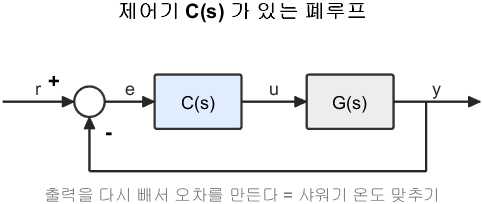

제어기 C(s) 가 있는 폐루프

**그림 파일** `loop_controller.png` — `common/dg_loop.m` 의 `dg_loop` · 다시 만들려면 `make_figures('loop_controller')`

**만드는 곳** — `common/dg_loop.m` 을 `dg_loop('controller', ...)` 로 부릅니다

그림 해석 — **오늘은 **$u$** 를 눈여겨봐야 합니다**

오늘 배우는 네 가지 제어기는 전부 $C(s)$** 안에 무엇을 적을 것인가**의 문제입니다. 루프 모양 자체는 하나도 안 바뀝니다.

## 0-1. 오늘 만들 제어기 네 가지를 한눈에

전부 **극점이나 영점을 더하는 일**입니다. 어디에 더하느냐만 다릅니다.

표만 보면 혼동하기 쉽습니다. 그림으로 보면 간단합니다.

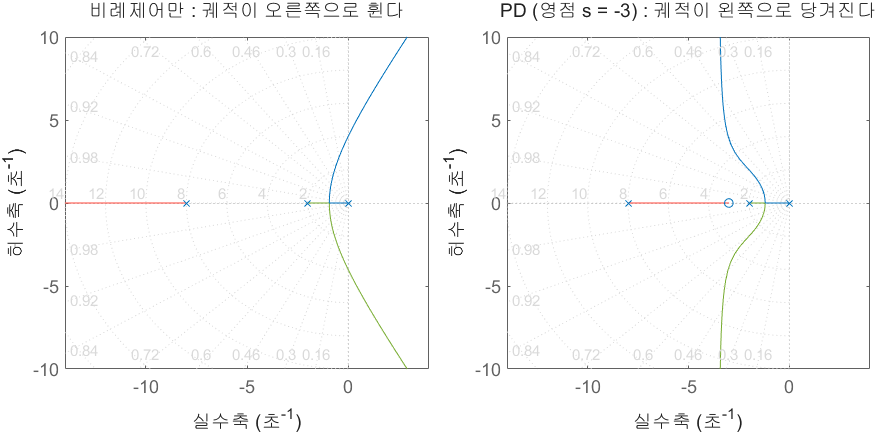

영점 하나로 궤적이 통째로 왼쪽으로 옮겨진다

**그림 파일** `w07_pd_locus.png` — `make_figures.m` 의 `fig_pd_locus` · 다시 만들려면 `make_figures('w07_pd_locus')`

**만드는 곳** — `make_figures.m` 의 `fig_pd_locus` **직접 바꿔 보려면** — 바로 아래 코드에서 `G0*(s+3)` 의 $3$ 을 $1$ 이나 $6$ 으로 바꿔 실행

그림 해석

**왼쪽에서 오른쪽으로 가는 것이 오늘 배우는 것의 전부입니다.**

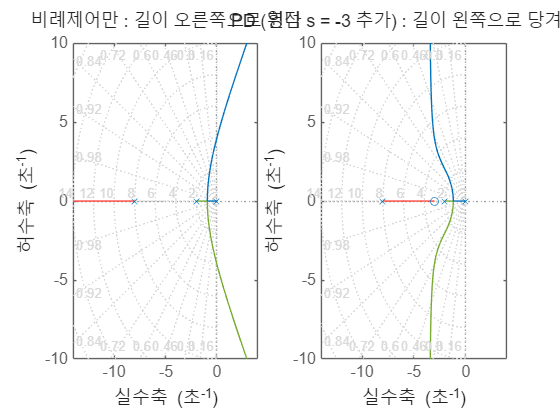

figure;
tiledlayout(1,2,'TileSpacing','compact');
G0 = 1/(s*(s+2)*(s+8));
nexttile
rlocus(G0); grid on;
xlim([-14 4]); ylim([-10 10]);
title('비례제어만 : 길이 오른쪽으로 휜다');
nexttile
rlocus(G0*(s+3)); grid on;
xlim([-14 4]); ylim([-10 10]);
title('PD (영점 s = -3 추가) : 길이 왼쪽으로 당겨진다');

오른쪽 그림에서 궤적이 통째로 왼쪽으로 옮겨졌습니다. **영점 하나를 더했을 뿐인데 갈 수 있는 곳이 달라졌습니다.** 이것이 오늘 배우는 것의 전부입니다.

## 1. 6주차의 벽

플랜트는 DC 모터 위치제어, 사양은 오버슈트 $20\%$ · 정착시간 $2$ 초입니다.

비례제어의 **최선**을 찾아 보면 정착시간이 $3.2$ 초입니다. 아무리 $K$ 를 잘 골라도 $2$ 초를 만들 수 없습니다.

이유는 6주차에서 진단했습니다.

- 궤적이 복소수가 된 뒤 **위로 곧장 올라간다**

- 올라가는 동안 실수부가 거의 변하지 않는다

- 정착시간은 실수부가 정하므로 방법이 없다

**근궤적은 정해진 길입니다.** 그 길 위에만 극점을 놓을 수 있습니다. 길이 사양 영역을 비껴가면 **길 자체를 바꿔야** 합니다.

## 1-1. 근궤적 설계 6단계

오늘부터 모든 설계는 이 순서로 합니다. 외우려 하지 말고 몸에 붙이십시오.

- **1단계** 사양을 적는다 — 오버슈트 몇 $\%$, 정착시간 몇 초, 오차 몇 $\%$

- **2단계** 사양을 $s$ 평면으로 옮긴다 — $\%OS \rightarrow \zeta$, $t_s \rightarrow \omega_n$

- **3단계** 근궤적을 그린다 — `rlocus(L)`, 여기서 $L$ 은 이득을 뺀 개루프

- **4단계** 사양 영역을 겹친다 — `sgrid(zeta, wn)`

- **5단계** 궤적이 영역을 지나는 곳의 이득을 읽는다

- **6단계** 검증한다 — `stepinfo` 로 실측, 그리고 **제어입력도 함께**

2단계에서 쓰는 두 공식은 4주차의 것입니다.


$$\zeta_{min} = \frac{-\ln(\%OS/100)}{\sqrt{\pi^2 + \ln^2(\%OS/100)}}, \qquad \omega_{n,min} = \frac{4}{\zeta_{min}\, t_s}$$


6단계를 빠뜨리는 사람이 많습니다. 반드시 하십시오.

- 5단계까지는 **근사식**입니다. 극점 두 개, 영점 없음을 가정한 공식이기 때문입니다

- 진짜 답은 6단계의 `stepinfo` 실측에서 나옵니다

- 그리고 제어입력을 안 본 설계는 절반만 한 설계입니다

3~5단계에서 **궤적이 사양 영역을 아예 안 지나면** 비례제어로는 끝입니다. 그때부터 오늘의 본론인 보상기 설계가 시작되고, 영점을 어디에 놓을지는 **2-0절의 각도 부족**으로 계산합니다. 6주차 1-2절의 각도 조건을 뒤집어 쓰는 것입니다.

[zm, wm] = spec2pole(10, 2);
fprintf('사양 : 오버슈트 10 %%, 정착시간 2 s\n');

사양 : 오버슈트 10 %, 정착시간 2 s


fprintf('  -> zeta >= %.4f ,  wn >= %.4f\n', zm, wm);

  -> zeta >= 0.5912 ,  wn >= 3.3832


## 1-2. 오늘 쓰는 새 도구 두 개

6주차에서 쓴 `rlocfind` 는 마우스로 궤적 위를 찍는 명령입니다. 감을 잡기에는 좋지만 두 가지가 불편합니다.

- 손이 떨리면 값이 달라진다

- 스크립트를 자동으로 돌릴 수 없다 (클릭을 기다리며 멈춘다)

그래서 같은 일을 숫자로 하는 함수 두 개를 `common` 폴더에 넣어 두었습니다.

**(1) rl_scan — 근궤적 위를 훑어 성능표를 만든다**

- **원리** — 이득 $K$ 를 촘촘히 바꿔 가며 매번 `feedback` 으로 폐루프를 닫고 `pole` · `stepinfo` · `dcgain` 으로 성능을 잰다. 전부 1, 4, 5 주차에서 배운 명령이다

- **입력** — `rl_scan(C1, G, Kvec)`. 여기서 `C1` 은 **이득을 뺀** 제어기이고 개루프는 $L(s) = K\,C_1(s)\,G(s)$ 가 된다. P 제어면 `C1 = 1`, PD 면 `C1 = (s+z)`

- **출력** — 표(table). 한 행이 이득 하나이고 열은 `K` `stable` `zeta` `wn` `OS` `ts` `Tp` `ess` `umax`

- **주의** — 표의 `zeta` 는 지배극점의 감쇠비다. **영점이 가까이 있으면 감쇠비가 커도 오버슈트가 클 수 있다.** 오버슈트는 항상 `OS` 열을 믿을 것

**(2) ctrl_input — 계단 지령에 대한 제어입력**

- **원리** — 지령에서 제어입력까지의 전달함수는 아래와 같다. 여기에 계단 $1/s$ 를 곱해 역라플라스 변환하면 $u(t)$ 가 나온다


$$\frac{U(s)}{R(s)} = \frac{C(s)}{1 + C(s)G(s)}$$


- **입력** — `ctrl_input(C, G)`. 여기서 `C` 는 **이득까지 포함한** 제어기

- **출력** — `[u, t, umax]`

- **주의** — 이상적인 PD 는 계단 지령에서 $t=0$ 에 임펄스를 만든다. 이 함수는 그 임펄스를 뺀 값을 돌려준다 (5절에서 자세히)

실제로 한 번 써 봅니다.

G_demo = 1/(s*(s+2)*(s+5));
disp(rl_scan(1, G_demo, [1 3 5 8], true));

    K    stable     zeta        wn         OS         ts        Tp      ess    umax
    _    ______    _______    _______    _______    ______    ______    ___    ____

    1    true            1    0.10805          0    36.973       NaN     0      1  
    3    true            1    0.41164          0    10.546       NaN     0      3  
    5    true      0.88047    0.97242    0.28638    4.8319    7.0461     0      5  
    8    true      0.64687     1.2138     6.7502    5.1415    3.5777     0      8  



## 1-3. 비례제어 설계 세 문제 — 되는 것 하나, 안 되는 것 둘

6단계를 세 문제에 적용해 봅니다. 세 문제 모두 똑같이 생겼습니다.

- 플랜트가 주어진다

- 사양이 주어진다

- 비례이득 $K$ 하나로 만족시킬 수 있는가?

**예제 A — 답이 있는 문제**


$$G(s) = \frac{1}{(s+1)(s+3)}, \qquad \%OS \le 10\%, \quad t_s \le 2\,\mathrm{s}$$


- 특성방정식이 $s^2 + 4s + (3+K) = 0$ 이므로 **두 근의 합이 항상 **$-4$ 다

- 복소근이면 실수부가 언제나 $-2$ 로 고정된다. 즉 **궤적이 세로 직선**이다

- 답 : $K \approx 2.1 \sim 8.4$. 아래쪽은 정착시간이, 위쪽은 오버슈트가 정한다

- 다만 정상상태 오차가 $27\%$ 나 남는다. 타입 0 이기 때문이다

**예제 B — 궤적이 사양을 만날 수 없는 문제**


$$G(s) = \frac{s+2}{(s+1)(s+5)}, \qquad \%OS \le 15\%, \quad T_p = 1.1 \sim 1.4\,\mathrm{s}$$


- 첨두시간이 있으려면 폐루프 극점이 **복소수** 여야 한다

- 그런데 실축 규칙으로 확인하면 궤적이 실축을 벗어나지 않는다

- 구간 $(-2,-1)$ 은 오른쪽에 극점 1 개라 홀수 $\rightarrow$ 궤적 위

- 구간 $(-5,-2)$ 는 극점 1 개 + 영점 1 개라 짝수 $\rightarrow$ 궤적 아님

- 즉 가지 하나는 $-1$ 에서 영점 $-2$ 로, 다른 하나는 $-5$ 에서 왼쪽 무한대로 간다. **두 가지가 만나지 않으므로 복소수가 될 일이 없다**

- 결론 : 진동이 아예 없어 첨두시간 사양이 **성립하지 않는다**

**예제 C — 사양끼리 싸우는 문제**


$$G(s) = \frac{5}{(s+1)(s+2)(s+5)}, \qquad e_{ss} \le 0.05, \quad \zeta \ge 0.35$$


- 오차 사양을 손으로 풀면 $K_p = K/2 \ge 19$, 즉 $K \ge 38$

- 안정 조건을 손으로 풀면 $8 \times 17 > 10 + 5K$, 즉 $K < 25.2$

- **겹치는 구간이 없다.** 오차를 지키려 하면 발산한다

세 경우 모두 원인이 같습니다.

- **비례이득은 궤적 위에서 점을 옮길 뿐, 궤적 자체는 못 바꾼다**

- 그러니 궤적이 가지 않는 곳은 영원히 갈 수 없다

이것이 오늘 보상기를 배우는 이유입니다.

GA = 1/((s+1)*(s+3));
TA = rl_scan(1, GA, linspace(0.5, 14, 1081));
okA = TA.stable & TA.OS <= 10 & TA.ts <= 2;
fprintf('예제 A 의 답 : K = %.2f ~ %.2f\n', min(TA.K(okA)), max(TA.K(okA)));

예제 A 의 답 : K = 2.12 ~ 8.44


GB = (s+2)/((s+1)*(s+5));
TB = rl_scan(1, GB, logspace(-2, 3, 200));
fprintf('예제 B : 첨두시간이 존재한 이득 %d 개 (진동이 아예 없음)\n', sum(~isnan(TB.Tp)));

예제 B : 첨두시간이 존재한 이득 0 개 (진동이 아예 없음)


GC = 5/((s+1)*(s+2)*(s+5));
TC = rl_scan(1, GC, linspace(0.5, 45, 1781));

fprintf('예제 C : 오차 0.05 는 K >= 38 을 요구, 안정 한계는 K = %.1f\n', ...
        min(TC.K(~TC.stable)));

예제 C : 오차 0.05 는 K >= 38 을 요구, 안정 한계는 K = 25.2


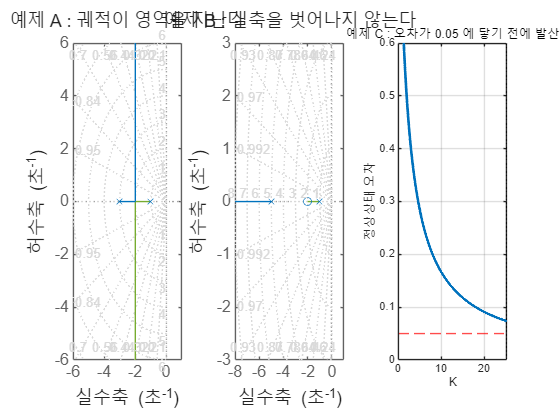

tiledlayout(1,3,'TileSpacing','compact');
nexttile
rlocus(GA); hold on; sgrid(zm, wm); xlim([-6 1]); ylim([-6 6]); grid on;
title('예제 A : 궤적이 영역을 지난다');
nexttile
rlocus(GB); grid on; xlim([-8 1]); ylim([-3 3]);
title('예제 B : 실축을 벗어나지 않는다');
nexttile
plot(TC.K, TC.ess, 'LineWidth', 2); hold on;
yline(0.05, 'r--'); xline(min(TC.K(~TC.stable)), 'k:');
ylim([0 0.6]); grid on; xlabel('K'); ylabel('정상상태 오차');
title('예제 C : 오차가 0.05 에 닿기 전에 발산');

## 2. PD 제어 — 영점을 하나 추가한다


$$C(s) = K_p + K_d s = K_d\left(s + \frac{K_p}{K_d}\right)$$


개루프에 곱하면 **영점 **$s = -z$** 하나가 추가**됩니다 ($z = K_p/K_d$).

6주차에서 배운 대로 영을 추가하면 $n-m$ 이 줄어 궤적이 **왼쪽으로 당겨집니다.**

왜 미분이 이런 일을 하는가 (직관)

- 비례제어는 "지금 얼마나 틀렸는가" 만 본다

- 미분제어는 "얼마나 빨리 틀려지고 있는가" 를 본다

- 빨리 다가가면 **미리 브레이크를 밟는** 셈이라 오버슈트가 줄고 진동이 잦아든다

4주차에서 본 것과 같습니다. 감쇠란 속도를 되먹이는 일이고, D 항이 그 일을 합니다.

## 2-0. 영점 위치를 계산으로 정하는 법 — 각도 부족

영점을 어디에 놓을지 **감으로 고르지 않고 계산으로 정하는 방법**이 있습니다. 6주차 1-2절의 각도 조건을 그대로 뒤집어 쓰면 됩니다.

논리는 세 줄입니다.

- 사양이 요구하는 **목표 극점** $s_d$ 를 먼저 정한다 (4주차 `spec2pole`)

- 그 점에서 $\angle G(s_d)$ 를 재 보면 $-180^\circ$ 에 **모자라거나 남는다**

- 그 차이를 **영점 하나가 채우도록** 위치를 정한다

이것을 **각도 부족**이라 합니다. 절차는 다섯 단계입니다.

4단계 식은 그림에서 바로 나옵니다. 목표 극점을 $s_d = -\sigma_d + j\omega_d$, 영점을 $-z$ 라 하면 영점에서 $s_d$ 로 가는 벡터는 $(z-\sigma_d) + j\omega_d$ 이므로


$$\tan\phi = \frac{\omega_d}{z - \sigma_d} \quad\Rightarrow\quad z = \sigma_d + \frac{\omega_d}{\tan\phi}$$


예제로 확인합니다. $G(s) = \frac{1}{s(s+4)}$ 에 사양 $\%OS = 16\%$, $t_s = 1$ s 입니다.

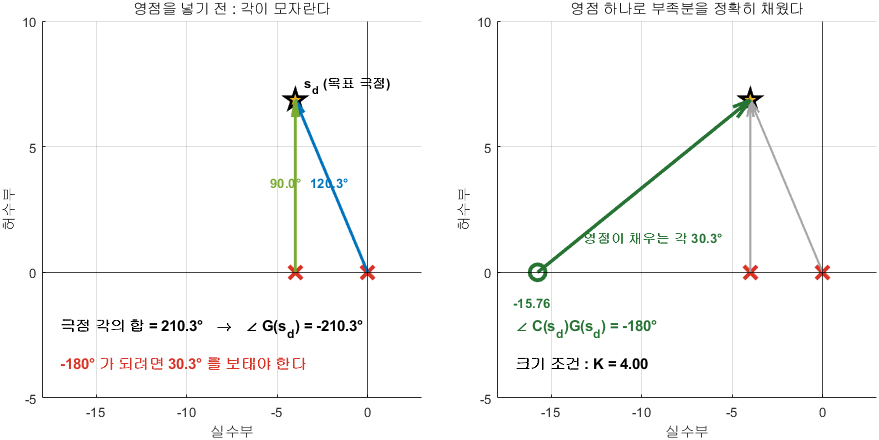

부족한 각을 영점 하나가 정확히 채운다

**그림 파일** `w07_angle_def.png` — `make_figures.m` 의 `fig_w07_angle_def` · 다시 만들려면 `make_figures('w07_angle_def')`

**만드는 곳** — `make_figures.m` 의 `fig_w07_angle_def` **직접 확인해 보려면** — 아래 코드에서 사양 `POS`, `ts` 를 바꿔 실행

그림 해석

아래 코드가 다섯 단계를 그대로 실행합니다.

POS_d = 16;  ts_d = 1;
[zeta_d, wn_d] = spec2pole(POS_d, ts_d);
sig_d = zeta_d*wn_d;
wd_d  = wn_d*sqrt(1 - zeta_d^2);
sd    = -sig_d + 1i*wd_d;

Gd0   = 1/(s*(s+4));
angG  = rad2deg(angle(evalfr(Gd0, sd)));
phi   = mod(-180 - angG, 360);
z_pd  = sig_d + wd_d/tand(phi);

Cpd   = s + z_pd;
K_pd  = 1/abs(evalfr(Cpd*Gd0, sd));

fprintf('=== 각도 부족으로 PD 설계 ===\n');

=== 각도 부족으로 PD 설계 ===


fprintf('1) 사양 %%OS=%g, ts=%g  ->  zeta=%.4f, wn=%.4f\n', POS_d, ts_d, zeta_d, wn_d);

1) 사양 %OS=16, ts=1  ->  zeta=0.5039, wn=7.9386


fprintf('   목표 극점 sd = %.4f %+.4fj\n', real(sd), imag(sd));

   목표 극점 sd = -4.0000 +6.8572j


fprintf('2) 극점 각의 합 = %.2f 도\n', sum(rad2deg(angle(sd - pole(Gd0).'))));

2) 극점 각의 합 = 210.26 도


fprintf('3) 보태야 할 각 = %.2f 도\n', phi);

3) 보태야 할 각 = 30.26 도


fprintf('4) 영점 위치    = %.4f\n', -z_pd);

4) 영점 위치    = -15.7553


fprintf('5) 이득         = %.4f\n', K_pd);

5) 이득         = 4.0000


fprintf('   -> C(s) = %.3f (s + %.3f) = %.3f s + %.3f\n', ...
        K_pd, z_pd, K_pd, K_pd*z_pd);

   -> C(s) = 4.000 (s + 15.755) = 4.000 s + 63.021


fprintf('   즉 Kp = %.3f, Kd = %.3f 인 PD 제어기입니다.\n', K_pd*z_pd, K_pd);

   즉 Kp = 63.021, Kd = 4.000 인 PD 제어기입니다.



T_pd = feedback(K_pd*Cpd*Gd0, 1);
fprintf('\n확인 : 폐루프 극점 %s\n', mat2str(round(pole(T_pd).', 4)));


확인 : 폐루프 극점 [-4+6.8572i -4-6.8572i]


fprintf('       목표 극점    %s\n', mat2str(round([sd conj(sd)], 4)));

       목표 극점    [-4+6.8572i -4-6.8572i]


info_pd = stepinfo(T_pd);
fprintf('       실측 오버슈트 %.2f %% (사양 %g %%), 정착시간 %.3f s (사양 %g s)\n', ...
        info_pd.Overshoot, POS_d, info_pd.SettlingTime, ts_d);

       실측 오버슈트 18.81 % (사양 16 %), 정착시간 0.964 s (사양 1 s)


## 2-0-1. 왜 오버슈트가 사양보다 크게 나오는가

위 결과를 보면 **극점은 목표 자리에 정확히 갔는데 오버슈트가 **$16\%$** 가 아니라 **$18.8\%$** 로 나옵니다.** 설계가 틀린 것이 아닙니다.

이유는 하나뿐입니다. $\%OS$ 공식은 **극점 두 개만 있고 영점이 없는** 표준 2차 시스템에서 유도한 것인데, 우리가 방금 **영점을 하나 넣었기** 때문입니다.

- 극점 배치는 각도 조건과 크기 조건이 보장한다 $\to$ **정확히 맞는다**

- 오버슈트는 영점이 더 키운다 $\to$ **공식보다 커진다**

그래서 실무 절차는 이렇습니다.

- 각도 부족으로 **첫 설계**를 한다 (출발점을 잡는 것)

- `stepinfo` 로 실측한다

- 사양을 못 맞추면 목표 극점을 조금 더 왼쪽·아래로 옮겨 **다시 계산한다**

이 되풀이가 2-3절에서 다루는 "감쇠비만 보면 안 된다" 의 실제 모습입니다. 그리고 2-1절의 표 비교 방식이 필요한 이유이기도 합니다.

목표를 조금 보수적으로 잡아 다시 해 보면 사양 안에 들어옵니다.

for POS_try = [16 12 9]
    [zt, wt] = spec2pole(POS_try, ts_d);
    sdt = -zt*wt + 1i*wt*sqrt(1-zt^2);
    ag  = rad2deg(angle(evalfr(Gd0, sdt)));
    ph  = mod(-180 - ag, 360);
    zt2 = zt*wt + wt*sqrt(1-zt^2)/tand(ph);
    Ct  = s + zt2;
    Kt  = 1/abs(evalfr(Ct*Gd0, sdt));
    it  = stepinfo(feedback(Kt*Ct*Gd0, 1));
    fprintf('목표 %%OS %2d %% -> 영점 %7.3f, K %6.3f -> 실측 OS %5.2f %%, ts %.3f s\n', ...
            POS_try, -zt2, Kt, it.Overshoot, it.SettlingTime);
end

목표 %OS 16 % -> 영점 -15.755, K  4.000 -> 실측 OS 18.81 %, ts 0.964 s
목표 %OS 12 % -> 영점 -12.782, K  4.000 -> 실측 OS 14.84 %, ts 0.731 s
목표 %OS  9 % -> 영점 -10.809, K  4.000 -> 실측 OS 11.79 %, ts 0.803 s


fprintf('--> 목표를 12 %% 로 낮춰 잡으면 실측 14.8 %% 로 사양 안에 들어옵니다.\n\n');

--> 목표를 12 % 로 낮춰 잡으면 실측 14.8 % 로 사양 안에 들어옵니다.



## 2-1. 영점 위치를 고르는 지침

각도 부족은 **한 점을 정확히 지나게** 하는 방법입니다. 그런데 사양은 보통 점이 아니라 **영역**으로 주어지므로, 그 영역 안에서 어느 자리가 가장 좋은지는 따로 따져야 합니다. 그때 쓰는 것이 아래 지침과 표 비교입니다.

딱 떨어지는 공식은 없습니다. 지침 세 가지가 있을 뿐입니다.

- **플랜트의 느린 극점 근처**에 둔다. 그 극점의 나쁜 영향을 상쇄한다

- **목표 극점의 실수부 근처**에 둔다. 궤적이 목표점을 지나게 만들기 좋다

- **너무 원점에 가깝게 두지 않는다.** 영점이 지배극점보다 원점에 가까우면 오버슈트가 오히려 커진다 (2주차의 영점 효과)

실제로는 후보를 서너 개 잡아 **표를 만들어 비교**합니다. 정답이 하나가 아니므로 **고른 이유를 말할 수 있는 것**이 더 중요합니다.

예를 들어 $G(s) = 1/((s+1)(s+4))$ 에 사양 $\%OS \le 10\%$, $t_s \le 2.5$ s, 그리고 구동기 한계 $|u| \le 10$ 을 걸고 $z = 1, 3, 6$ 을 비교하면 이렇습니다.

- 세 경우 모두 $\max|u|$ 가 $9$ 를 넘는다. 즉 $K$ 의 상한을 정한 것은 오버슈트가 아니라 **구동기 한계**다

- 같은 제어입력 예산 안에서 오차를 결정하는 것은 $K_p = Kz/4$ 다

- $z = 1$ 이면 $K_p = 0.92$, $z = 6$ 이면 $K_p = 10.92$ 로 $12$ 배 차이가 난다

- 그래서 **영점을 왼쪽으로 옮길수록 같은 힘으로 더 정확해진다**

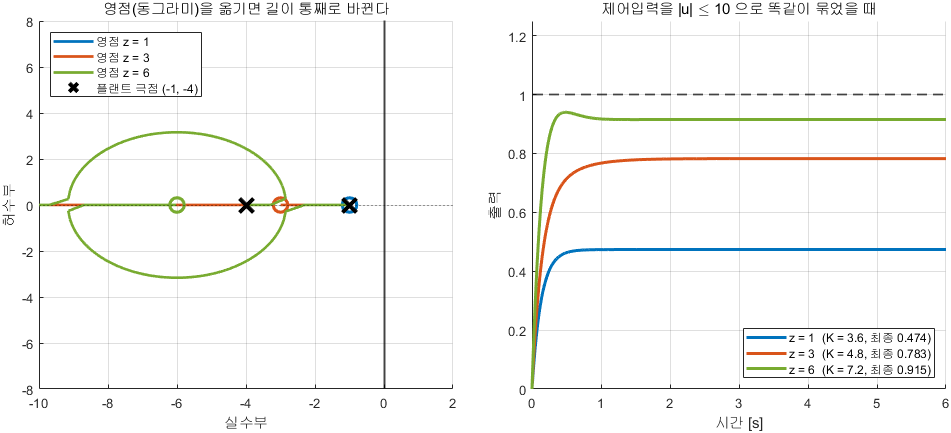

같은 힘 예산에서 영점을 왼쪽에 둘수록 정확해진다

**그림 파일** `w07_zero_place.png` — `make_figures.m` 의 `fig_w07_zero_place` · 다시 만들려면 `make_figures('w07_zero_place')`

**만드는 곳** — `make_figures.m` 의 `fig_w07_zero_place` **직접 바꿔 보려면** — `W07_03_pd_design_practice.m` 의 **2절**에서 `z` 목록에 $10$ 을 추가해 보십시오

그림 해석

왜 $z$ 가 크면 $K$ 를 크게 쓸 수 있는가 — 제어입력의 처음 크기가 대략 $K$ 에 비례하는데, 정상상태 정확도는 $K_p = Kz/4$ 가 정하기 때문입니다. $z$ 를 키우면 $K$** 를 안 키우고도 **$K_p$** 가 커집니다.**

GD = 1/((s+1)*(s+4));
fprintf('    z     고른 K   오버슈트[%%]   오차     max|u|\n');

    z     고른 K   오버슈트[%]   오차     max|u|


for z = [1 3 6]
    Ti = rl_scan(s+z, GD, linspace(0.2, 40, 300), true);
    ok = Ti.stable & Ti.OS <= 10 & Ti.ts <= 2.5 & Ti.umax <= 10;
    sub = Ti(ok,:); [~, j] = min(sub.ess);
    fprintf('  %5d  %8.2f  %10.2f  %8.4f  %8.2f\n', ...
            z, sub.K(j), sub.OS(j), sub.ess(j), sub.umax(j));
end

      1      3.66        0.00    0.5221      9.74
      3      4.99        0.00    0.2108      9.94
      6      7.25        2.71    0.0842      9.10


## 2-2. 영점을 플랜트 극점 위에 놓으면 — 해도 되는 것과 절대 안 되는 것

영점을 플랜트 극점과 **같은 자리**에 놓으면 그 극점이 약분되어 사라집니다.


$$L(s) = \frac{K(s+4)}{(s+1)(s+4)} = \frac{K}{s+1}$$


개루프가 1차로 줄어드니 진동이 아예 없습니다. 종이 위에서는 최고의 설계입니다.

**안정한 극점을 지우는 것 — 해도 됩니다**

- 실무에서도 흔히 쓰는 기법이다

- 상쇄가 정확히 맞지 않아도 (예 : 실제 극점이 $-4$ 가 아니라 $-3$ 이어도) 폐루프 극점은 여전히 좌반면에 남는다. 성능이 조금 달라질 뿐이다

**불안정한 극점을 지우는 것 — 절대 금지입니다**


$$G(s) = \frac{1}{(s-1)(s+4)}, \qquad D(s) = K(s-1)$$


- 손으로 약분하면 $L = K/(s+4)$ 가 되어 아주 안정해 보인다

- **계단응답을 그려 봐도 멀쩡해 보인다.** 그래서 더 무섭다

- 그런데 폐루프 극점을 실제로 계산하면 $s = +1$ 이 그대로 남아 있다

- 제어기 영점이 그 극점을 **가려 버렸을 뿐** 없앤 것이 아니다

- 아주 작은 외란 하나만 들어와도 그 순간부터 발산한다

교훈은 하나입니다 — **계단응답만 보지 말고 폐루프 극점을 직접 확인하십시오.**

G_unst = 1/((s-1)*(s+4));
T_bad  = feedback(5*(s-1)*G_unst, 1);
S_bad  = feedback(G_unst, 5*(s-1));
t_bad  = linspace(0, 8, 500)';
fprintf('불안정 극점 상쇄 : 폐루프 극점 %s\n', mat2str(round(pole(T_bad)', 3)));

불안정 극점 상쇄 : 폐루프 극점 [-9 1]


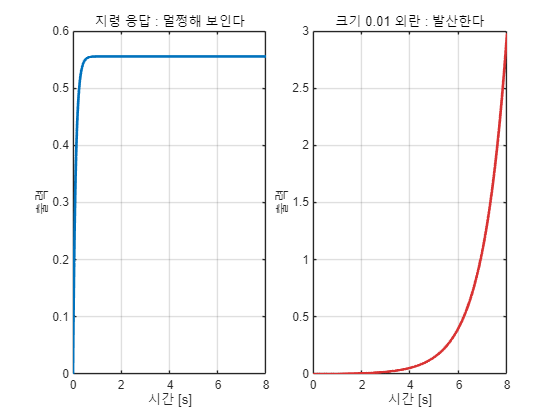

tiledlayout(1,2,'TileSpacing','compact');
nexttile
plot(t_bad, step(T_bad, t_bad), 'LineWidth', 2); grid on;
xlabel('시간 [s]'); ylabel('출력'); title('지령 응답 : 멀쩡해 보인다');
nexttile
plot(t_bad, step(0.01*S_bad, t_bad), 'LineWidth', 2, 'Color', [0.85 0.2 0.2]); grid on;
xlabel('시간 [s]'); ylabel('출력'); title('크기 0.01 외란 : 발산한다');

## 2-3. 감쇠비만 보면 안 됩니다 — 영점이 만드는 오버슈트

4주차에서 배운 공식은 이것입니다.


$$\%OS = 100\,e^{-\pi\zeta/\sqrt{1-\zeta^2}}$$


그런데 이 공식에는 조건이 붙습니다. **극점 두 개, 영점 없음** 일 때만 맞습니다.

실제 예를 봅니다. $G(s) = 5/((s+1)(s+2)(s+5))$ 에 PD $26(s+1.5)$ 를 붙이면

- 폐루프 극점 : $-3.25 \pm 11.26j$ 와 $-1.49$

- 지배극점은 실극점 $-1.49$ 이므로 감쇠비는 $1$ — 공식대로면 오버슈트 $0\%$

- **실측 오버슈트는 **$40\%$ 다

범인은 폐루프 영점 $-1.5$ 입니다. 지배극점 바로 옆에 있습니다. 같은 극점을 그대로 두고 영점만 지우면 오버슈트가 $0\%$ 가 됩니다.

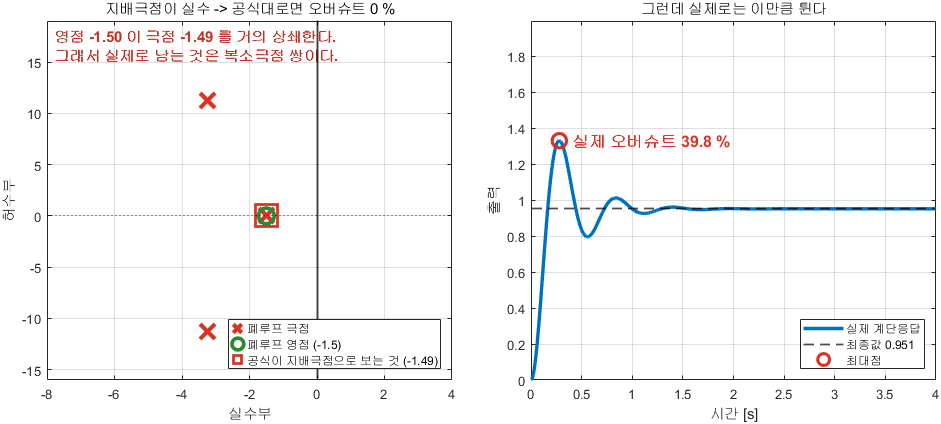

극점만 보면 오버슈트 0 %, 실제로는 39.8 %

**그림 파일** `w07_zero_os.png` — `make_figures.m` 의 `fig_w07_zero_overshoot` · 다시 만들려면 `make_figures('w07_zero_os')`

**만드는 곳** — `make_figures.m` 의 `fig_w07_zero_overshoot` **직접 확인해 보려면** — 바로 아래 코드가 영점을 지운 것과 남긴 것을 나란히 그려 줍니다

그림 해석

왼쪽에서 "지배극점" 으로 뽑힌 것이 사실은 상쇄되어 사라지고, 남은 복소극점 쌍이 응답을 만들고 있습니다. **극점 목록만 보고 원점에 가까운 것을 지배극점이라 부르면 이런 함정에 빠집니다.**

기억할 것

- **감쇠비는 참고값이고, 오버슈트는 stepinfo 실측이 답이다**

- 영점이 지배극점 가까이 있으면 오버슈트가 크게 늘어난다

- 그래서 설계 6단계의 마지막 검증이 반드시 필요하다

GE = 5/((s+1)*(s+2)*(s+5));
TE = feedback(26*(s+1.5)*GE, 1);
TE_nz = zpk([], pole(TE), 1);  TE_nz = TE_nz/dcgain(TE_nz);
fprintf('영점 있음 : 오버슈트 %.2f %%\n', getfield(stepinfo(TE),'Overshoot'));

영점 있음 : 오버슈트 39.79 %


fprintf('영점 없음 : 오버슈트 %.2f %%\n', getfield(stepinfo(TE_nz),'Overshoot'));

영점 없음 : 오버슈트 0.00 %


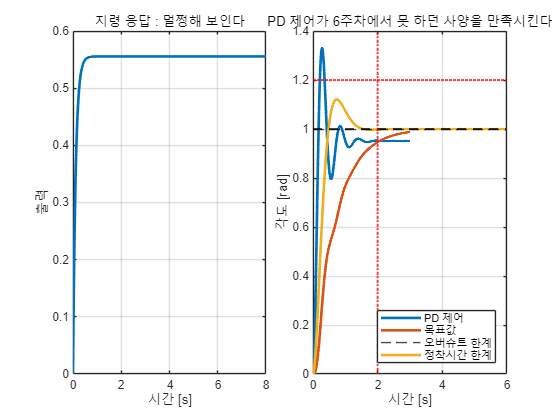

tt = linspace(0, 3, 600)';
plot(tt, step(TE, tt), 'LineWidth', 2); hold on;
plot(tt, step(TE_nz, tt), 'LineWidth', 2);
yline(1, 'k--'); grid on;
xlabel('시간 [s]'); ylabel('출력');
legend('영점 있음 (실제)', '영점 없음 (같은 극점)', '목표', 'Location', 'southeast');
title('오버슈트를 만든 것은 극점이 아니라 영점');
%
% 실무에서는 후보 몇 개를 놓고 다 해 본 뒤 고릅니다.
% 실습에서 해 본 결과는 이렇습니다.
%
% - $z=1$ — 오버슈트 $0\%$ 인데 정착시간 $3.4$ 초. **불합격**
% - $z=3$ — 오버슈트 $12.1\%$, 정착시간 $1.28$ 초. **합격**
% - $z=6$ — 오버슈트 $32.3\%$. 불합격
% - $z=12$ — 오버슈트 $49.7\%$. 불합격
%
% $z=3$ 으로 **6주차에서 불가능했던 사양을 만족**시켰습니다.
% 이것이 "길을 바꾼다" 는 말의 뜻입니다.
[G, ~] = plant_dcmotor('position');
[zm, wm, st] = spec2pole(20, 2);
C_pd = 18.908*(s+3);
t = 0:0.005:6;
plot(t, step(feedback(C_pd*G,1), t), 'LineWidth', 2); hold on
yline(1,'k--','LineWidth',1.5); yline(1.2,'r:','LineWidth',1.5)
xline(2,'r:','LineWidth',1.5); grid on
xlabel('시간 [s]'); ylabel('각도 [rad]')
title('PD 제어가 6주차에서 못 하던 사양을 만족시킨다')
legend('PD 제어','목표값','오버슈트 한계','정착시간 한계','Location','southeast')

## 3. PI 제어 — 원점에 극점을 추가한다


$$C(s) = K_p + \frac{K_i}{s} = \frac{K_p\left(s + K_i/K_p\right)}{s}$$


**원점 극점 하나와 영점 하나**를 함께 추가합니다.

- 원점 극점 — 시스템 타입을 하나 올린다 → 정상상태 오차 제거 (5주차)

- 영점 — 그 극점이 만드는 나쁜 영향을 완화한다

5주차에서 배운 대로 원점 극점은 궤적을 오른쪽으로 밀어 불안정하게 만듭니다. 그래서 PI 는 **반드시 영점을 함께** 붙입니다. 영점이 없으면 순수 적분기가 되어 거의 항상 불안정해집니다.

영점 위치 지침

- **원점에 아주 가깝게** 둔다. 보통 지배극점의 $1/10$ 정도

- 이유 — 원점 극점과 영점이 거의 상쇄되어 궤적의 나머지는 거의 그대로 두면서 정상상태 오차만 없애기 위해서

## 4. PD 와 PI 는 서로를 대신할 수 없다

선택 기준은 단순합니다. **무엇이 문제인가** 를 보면 됩니다.

- 과도응답이 문제다 (느리다, 진동한다) → **PD**

- 정상상태 오차가 문제다 → **PI**

- 둘 다 문제다 → **PID** (11주차)

주의

- **PD 는 정상상태 오차를 개선하지 못한다.** 영점은 타입을 바꾸지 않는다

- **PI 는 과도응답을 나쁘게 만든다.** 극점을 추가하니 느려진다

실제로 확인해 보면 P 제어와 PD 제어의 타입은 둘 다 $1$ 로 같고, PI 를 붙여야 타입이 $2$ 가 됩니다.

타입 0 플랜트 $G = 1/((s+1)(s+4))$ 에 셋을 붙여 나란히 보겠습니다.

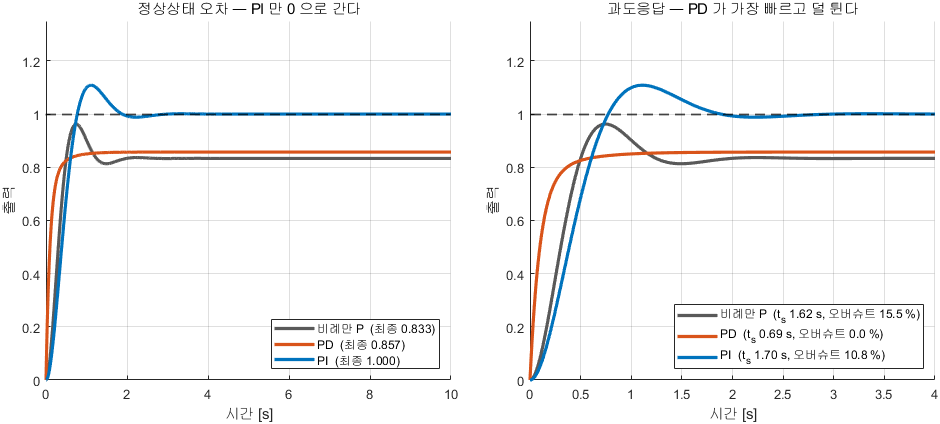

PD 는 과도응답을, PI 는 정상상태를 고친다

**그림 파일** `w07_pd_vs_pi.png` — `make_figures.m` 의 `fig_w07_pd_vs_pi` · 다시 만들려면 `make_figures('w07_pd_vs_pi')`

**만드는 곳** — `make_figures.m` 의 `fig_w07_pd_vs_pi` **직접 바꿔 보려면** — `W07_02_pd_and_pi.m` 의 **4절**에서 제어기 이득을 바꿔 가며 같은 비교를 해 볼 수 있습니다

그림 해석 — **왼쪽은 오래, 오른쪽은 짧게 본 같은 응답입니다**

두 그림을 한 문장으로 — **PD 는 빠르지만 정확하지 않고, PI 는 정확하지만 느립니다.** 둘 다 필요하면 PID 이고, 11주차에서 다룹니다.

## 4-1. 1-3 절의 예제 C 를 다시 — PD 로는 안 되고 PI 로는 됩니다

예제 C 는 비례제어로 불가능했습니다. 그러면 PD 로는 가능한가?

- PD 를 붙이면 궤적이 왼쪽으로 가니 이득을 더 크게 쓸 수 있다

- 실제로 오차 $0.05$ 는 만족시킬 수 있다

- **그런데 그때 오버슈트가 **$37 \sim 57\%$** 다.** 어떤 영점 위치를 골라도 그렇다

이유는 4절에서 말한 그대로입니다.

- PD 는 시스템 타입을 바꾸지 못한다. 타입 0 은 PD 를 붙여도 타입 0 이다

- 오차를 $1/20$ 로 줄이려면 $K_p$ 를 $20$ 배로 만들어야 하고, 그러려면 이득을 크게 써야 하고, 그러면 오버슈트가 터진다

정답은 PI 입니다. 원점의 극점이 타입을 $0$ 에서 $1$ 로 올려 줍니다.


$$C(s) = K\,\frac{s+a}{s} \qquad \Rightarrow \qquad e_{ss} = 0$$


세 설계를 나란히 놓으면 이렇습니다.

- **P** — 오버슈트는 지켰지만 오차 $33\%$

- **PD** — 오차는 지켰지만 오버슈트 $40\%$

- **PI** — 둘 다 지켰고 오차는 정확히 $0$

**사양을 보고 도구를 고르십시오. 오차 사양이면 적분기입니다.**

TPI = rl_scan((s+0.8)/s, GE, linspace(0.2, 25, 300), true);
okPI = TPI.stable & TPI.OS <= 20 & TPI.ts <= 6;
subPI = TPI(okPI,:); [~, jPI] = min(subPI.ts);
fprintf('PI 설계 : K = %.2f  오버슈트 %.2f %%  정착시간 %.2f s  오차 %.5f\n', ...
        subPI.K(jPI), subPI.OS(jPI), subPI.ts(jPI), subPI.ess(jPI));

PI 설계 : K = 1.86  오버슈트 1.43 %  정착시간 2.70 s  오차 0.00000


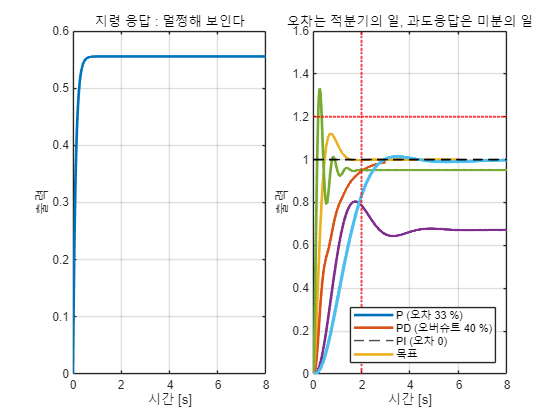

TP0 = rl_scan(1, GE, linspace(0.2, 25, 300));
okP0 = TP0.stable & TP0.OS <= 20;
subP0 = TP0(okP0,:); [~, jP0] = min(subP0.ess);
tE = linspace(0, 8, 800)';
plot(tE, step(feedback(subP0.K(jP0)*GE,1), tE), 'LineWidth', 2); hold on;
plot(tE, step(TE, tE), 'LineWidth', 2);
plot(tE, step(feedback(subPI.K(jPI)*(s+0.8)/s*GE,1), tE), 'LineWidth', 2.5);
yline(1, 'k--'); grid on; ylim([0 1.6]);
xlabel('시간 [s]'); ylabel('출력');
legend('P (오차 33 %)', 'PD (오버슈트 40 %)', 'PI (오차 0)', '목표', ...
       'Location', 'southeast');
title('오차는 적분기의 일, 과도응답은 미분의 일');

## 4-2. 제어입력을 사양에 넣는다

지금까지의 사양은 전부 "출력이 어떠해야 한다" 였습니다. 현장에서는 사양이 하나 더 붙습니다.

- 모터는 정해진 전압까지만 낸다

- 밸브는 완전히 열리는 데까지만 열린다

- 추진기는 정해진 추력까지만 낸다

그 이상을 요구하는 설계는 **종이 위에서만 맞습니다.** 그래서 제어입력 한계를 처음부터 사양에 넣습니다. 그러면 두 가지가 좋아집니다.

- 답이 좁아진다 — 출력 사양만 볼 때보다 훨씬 적은 후보가 남는다

- 고르는 기준이 생긴다 — **사양을 만족하는 것 중 **$\max|u|$** 가 가장 작은 것**

왜 가장 작은 것을 고르는가

- 구동기가 덜 뜨거워지고 덜 닳는다

- 전력을 덜 쓴다

- 모델이 조금 틀려도 한계에 부딪히지 않을 여유가 생긴다

**손으로 알 수 있는 공식**

계단 지령에서 제어입력이 가장 큰 순간은 보통 $t=0$ 입니다. 그때 오차가 가장 크기 때문입니다.

**비례제어**는 한 줄입니다. $t=0^+$ 에서 출력은 아직 $0$ 이므로 $e(0)=1$ 이고


$$u(0^+) = K\,e(0^+) = K$$


즉 **최대 제어입력이 이득 그 자체**입니다.

## 4-2-1. PD 의 $u(0^+)$ 는 플랜트의 상대차수에 따라 달라진다

PD 는 비례제어처럼 간단하지 않습니다. **조건에 따라 답이 두 가지**로 갈립니다. 많이들 하나만 외우고 틀리는 자리이므로 유도해 둡니다.

제어기를 $C = K(s+z)$, 플랜트를 $G = \frac{N(s)}{D(s)}$ 라 하고 분모 차수를 $n$, 분자 차수를 $m$, **상대차수**를 $r = n-m$ 이라 합니다.

지령에서 제어입력까지의 전달함수는 (1주차에서 유도한 그 꼴)


$$\frac{U}{R} = \frac{C}{1+CG} = \frac{K(s+z)\,D}{D + K(s+z)\,N}$$


계단 지령이면 $R = 1/s$ 이므로


$$U(s) = \frac{K(s+z)\,D}{s\left[\,D + K(s+z)N\,\right]}$$


분자 차수는 $n+1$, 분모 차수도 $n+1$ 입니다 ($r \ge 2$ 이면). **분자와 분모의 차수가 같으면 상수항이 하나 떨어져 나오고, 그 상수가 시간영역에서 임펄스**가 됩니다. 그것이 5절의 미분 킥입니다.

그 임펄스(크기 $K$)를 떼어 내고 남은 부분의 $t=0^+$ 값을 구합니다.


$$U(s) - K = \frac{K\left[\,z\,D - K\,s(s+z)N\,\right]}{s\left[\,D + K(s+z)N\,\right]}$$


초기값 정리 $u(0^+) = \lim_{s\to\infty} s\left[U(s)-K\right]$ 를 쓰면


$$u(0^+) = \lim_{s\to\infty} \frac{K\left[\,z\,D - K\,s(s+z)N\,\right]}{D + K(s+z)N}$$


**여기서 분자의 두 덩어리 중 어느 쪽이 이기는지가 상대차수로 갈립니다.**

- $r = 2$ 이면 두 덩어리가 **같은 차수**라 둘 다 남는다

- $r \ge 3$ 이면 둘째가 차수가 낮아 **사라진다**

플랜트의 분자 최고차 계수(고주파 이득)를 $b$ 라 하면 결론은 이렇습니다.

$r=2$** 쪽이 재미있습니다.** $K$ 를 $z/b$ 에 가깝게 잡으면 초기 제어입력이 사라집니다. 다만 그 자리가 좋은 설계라는 뜻은 아닙니다. 초기값만 작을 뿐입니다.

아래에서 두 경우를 모두 확인합니다.

Kq0 = 2;  zq0 = 5;
fprintf('=== PD 의 초기 제어입력 ===\n');

=== PD 의 초기 제어입력 ===


fprintf('  %-24s %-6s %-12s %s\n', '플랜트', '상대차수', 'u(0+) 실측', '공식');

  플랜트                      상대차수   u(0+) 실측     공식


Gq1 = 1/(s*(s+2));                 % r = 2
Gq2 = 1/(s*(s+2)*(s+5));           % r = 3
[uq1, ~] = ctrl_input(Kq0*(s+zq0), Gq1, linspace(0,5,5001)');
[uq2, ~] = ctrl_input(Kq0*(s+zq0), Gq2, linspace(0,5,5001)');
fprintf('  %-24s %-6d %-12.4f K(z-Kb) = %.4f\n', '1/(s(s+2))',      2, uq1(1), Kq0*(zq0-Kq0));

  1/(s(s+2))               2      6.0000       K(z-Kb) = 6.0000


fprintf('  %-24s %-6d %-12.4f K z     = %.4f\n', '1/(s(s+2)(s+5))', 3, uq2(1), Kq0*zq0);

  1/(s(s+2)(s+5))          3      10.0000      K z     = 10.0000


fprintf('  --> 아래 예제의 플랜트는 상대차수 3 이므로 K*z 쪽을 씁니다.\n\n');

  --> 아래 예제의 플랜트는 상대차수 3 이므로 K*z 쪽을 씁니다.



%
% **예 — 제어입력까지 넣어 설계한 결과**
%
% $$G(s) = \frac{1}{s(s+2)(s+5)}, \quad T_s < 5.2\,\mathrm{s},\; M_p < 1\%,\; |u| \le 5$$
%
% - 안정 조건만 : $K < 70$
% - 정착시간까지 : $K = 4.79 \sim 10.67$
% - 오버슈트까지 : $K = 4.79 \sim 5.54$
% - 제어입력까지 : $K = 4.79 \sim 5.00$
% - 그중 $\max|u|$ 가 가장 작은 것은 $K^* = 4.79$
%
% 사양 구간이 이렇게 좁아집니다. 이럴 때가 바로 비례제어를 버릴 때입니다.
Gq = 1/(s*(s+2)*(s+5));
Tq = rl_scan(1, Gq, linspace(0.5, 12, 1151), true);
okq = Tq.stable & Tq.ts < 5.2 & Tq.OS < 1 & Tq.umax <= 5;
fprintf('만족하는 이득 : K = %.2f ~ %.2f\n', min(Tq.K(okq)), max(Tq.K(okq)));

만족하는 이득 : K = 4.79 ~ 5.00


## 4-3. `controlSystemDesigner` — 마우스로 하는 근궤적 설계

MATLAB 에는 같은 일을 화면에서 하는 앱이 있습니다.

- **원리** — 근궤적, 계단응답, 보드선도를 한 화면에 띄우고 이득이나 극영점을 마우스로 끌면 모든 창이 동시에 갱신된다

- **입력** — `controlSystemDesigner(G)` 또는 `controlSystemDesigner(G, C)`

- **출력** — 화면. 설계를 끝내면 Export 로 제어기를 워크스페이스에 내보낸다

쓰는 법

- Root Locus 창에서 마우스로 이득(분홍 네모)을 끈다

- 오른쪽 클릭 $\rightarrow$ Design Requirements $\rightarrow$ New 로 사양 영역을 겹친다

- Add Pole or Zero $\rightarrow$ Real Zero 로 PD 영점을 넣고 끌어 본다

- Step 창에서 오버슈트와 정착시간을 실시간으로 확인한다

주의 세 가지

- 앱은 **제어입력을 보여 주지 않는다.** 반드시 `ctrl_input` 으로 따로 확인할 것

- 마우스로 끈 값은 재현이 어렵다. 최종 값은 스크립트에 적어 둘 것

- 앱이 만든 제어기의 표기가 $K(s+z)$ 가 아니라 $K(1+s/z)$ 일 수 있다. Export 한 뒤 `zpk` 로 확인할 것

예제 — 명령창에 직접 입력해 보십시오

- `G = tf(1, [1 2 0]);`

- `controlSystemDesigner(G)`

## 5. 그런데 PD 는 실제로 만들 수 없습니다

여기가 오늘의 두 번째 주제입니다.


$$C(s) = K_d(s+z)$$


분자에 $s$ 가 있고 분모에는 없습니다. 이런 것을 **부적절**(improper)하다고 합니다. 분자 차수가 분모보다 높으면 물리적으로 만들 수 없습니다.

왜 못 만드는가

- $s$ 를 곱한다는 것은 **미분한다**는 뜻이다

- 완벽한 미분기는 존재하지 않는다. 주파수가 높아질수록 이득이 무한히 커진다

실제로 계산해 보면

- $1\,\mathrm{rad/s}$ — 이득 $59.8$

- $100\,\mathrm{rad/s}$ — 이득 $1891$

- $1000\,\mathrm{rad/s}$ — 이득 $18900$

- $10000\,\mathrm{rad/s}$ — 이득 $189000$

**끝없이 커집니다.**

2-3 절에서 쓴 PD $26(s+1.5)$ 로 같은 계산을 하고, Lead 와 겹쳐 보겠습니다.

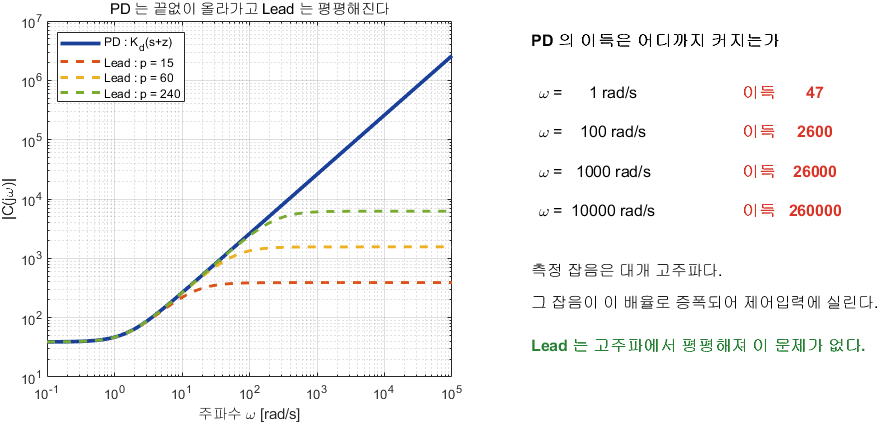

PD 는 끝없이 올라가고 Lead 는 평평해진다

**그림 파일** `w07_pd_improper.png` — `make_figures.m` 의 `fig_w07_pd_improper` · 다시 만들려면 `make_figures('w07_pd_improper')`

**만드는 곳** — `make_figures.m` 의 `fig_w07_pd_improper` **직접 확인해 보려면** — `W07_05_lead_and_lag.m` 의 **2절**이 같은 비교를 표와 그림으로 출력합니다

그림 해석 — **가로세로 둘 다 로그 눈금**입니다

**저주파에서는 같고 고주파에서만 다르다** — 이것이 Lead 를 쓰는 이유입니다. 제어 성능은 저주파가 정하고, 잡음은 고주파에 있기 때문입니다.

## 5-1. MATLAB 도 거부합니다

제어입력을 구하려고 `step(feedback(C_pd, G))` 를 부르면 MATLAB 이 이렇게 답합니다.

"비적정(비인과적) 모델의 시간 응답을 시뮬레이션할 수 없습니다"

미래의 입력을 알아야 계산되는 꼴이기 때문입니다. **"PD 는 실제로 만들 수 없다" 는 말이 여기서 그대로 확인됩니다.**

이것 하나만으로도 실무에서 PD 대신 Lead 를 쓰는 이유가 충분합니다.

**그런데 4-2 절에서는 PD 의 제어입력을 계산했는데요?**

좋은 질문입니다. 정확히 말하면 이렇습니다.

- 계단 지령은 $t=0$ 에서 순간적으로 뛴다

- 이상적인 미분기는 그 순간의 기울기를 무한대로 본다

- 그래서 $u(t)$ 안에는 $t=0$ 에 **크기 **$K$** 짜리 임펄스**가 들어 있다

- 그 임펄스를 뺀 나머지는 유한하고 계산할 수 있다

`ctrl_input` 은 그 임펄스를 빼고 **직후부터의 최대값**을 돌려줍니다. 후보들을 같은 잣대로 비교하는 것이므로 설계에서 순위를 매기는 데는 문제가 없습니다. 다만 **그 임펄스가 실제로는 어떻게 되는가** 가 바로 지금부터의 이야기입니다.

## 6. Lead 보상기 — PD 에 극점을 하나 붙인 것


$$C(s) = K_c\,\frac{s+z}{s+p}, \qquad p > z$$


PD 와 비교하면

- **PD** — $K_d(s+z)$. 분모 없음. 고주파 이득이 무한대

- **Lead** — $K_c(s+z)/(s+p)$. 분모 있음. 고주파 이득이 $K_c$ 로 제한

이름이 Lead(앞섬)인 이유는 위상을 앞서게 만들기 때문입니다. 위상 이야기는 9~10주차에서 제대로 다룹니다. 오늘은 근궤적 관점으로만 봅니다.

근궤적 관점

- 영점 $s=-z$ — 궤적을 왼쪽으로 당긴다 (PD 와 같은 효과)

- 극점 $s=-p$ — 궤적을 오른쪽으로 민다 (원하지 않는 부작용)

그래서 극점을 **영점보다 훨씬 왼쪽에** 둡니다. 그러면 극점의 나쁜 영향이 작아지고 영점의 좋은 효과만 남습니다.

**경험칙** — $p$ 를 $z$ 의 $5\sim20$ 배로

## 6-1. Lead 설계에는 맞바꿈이 있다

실습에서 $z=2$ 로 고정하고 $p$ 만 바꿔 본 결과입니다.

- $p=15$ — $K_c = 265$, 최대입력 $265\,\mathrm{V}$, 오버슈트 $8.2\%$, 정착 $1.17\,\mathrm{s}$

- $p=30$ — $K_c = 552$, 최대입력 $552\,\mathrm{V}$, 오버슈트 $4.1\%$, 정착 $1.04\,\mathrm{s}$

- $p=60$ — $K_c = 1135$, 최대입력 $1135\,\mathrm{V}$, 오버슈트 $2.6\%$, 정착 $0.94\,\mathrm{s}$

$p$** 를 키우면 성능은 좋아지지만 제어입력이 커집니다.**

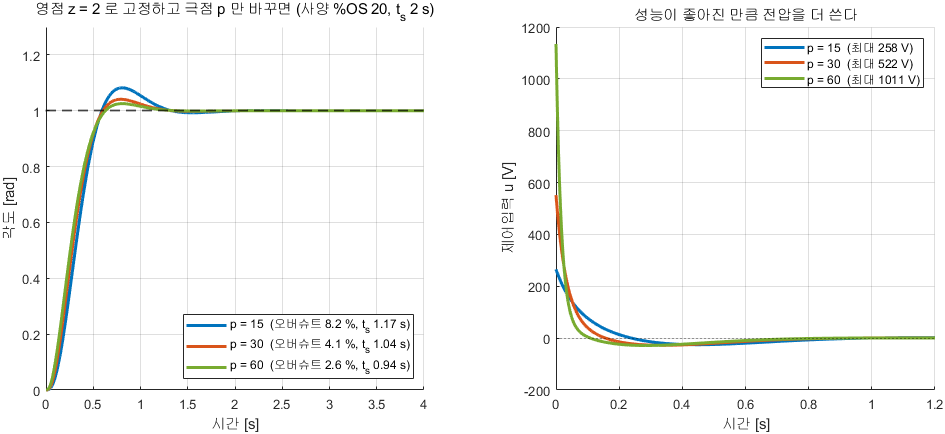

p 를 키우면 성능도 전압도 함께 오른다

**그림 파일** `w07_lead_tradeoff.png` — `make_figures.m` 의 `fig_w07_lead_tradeoff` · 다시 만들려면 `make_figures('w07_lead_tradeoff')`

**만드는 곳** — `make_figures.m` 의 `fig_w07_lead_tradeoff` **직접 바꿔 보려면** — `W07_05_lead_and_lag.m` 의 **3절** 후보 표에서 `p_cand` 에 $120$ 을 추가해 보십시오

그림 해석

**왼쪽에서 초록을 고르고 싶어지지만, 오른쪽을 보면 **$1011$** V 입니다.** $24$ V 짜리 드라이버로는 어느 것도 못 씁니다. 그래서 실제 설계는 "성능이 가장 좋은 것" 이 아니라 **"구동기가 낼 수 있는 것 중 가장 좋은 것"** 을 고르는 일이 됩니다.

즉 "가장 좋은 성능" 을 고르면 안 됩니다. 구동기가 낼 수 있는 전압 안에서 골라야 합니다. 6주차의 교훈이 여기서도 그대로 적용됩니다.

## 7. Lag 보상기 — PI 의 안전한 버전

PI 의 문제는 원점 극점입니다.

- 원점 극점은 궤적을 오른쪽으로 밀어 불안정하게 만든다 (5주차)

- 적분기는 포화와 만나면 와인드업을 일으킨다 (11주차)

Lag 는 극점을 원점이 아니라 **원점 아주 가까이**에 둡니다.


$$C(s) = K_c\,\frac{s+z}{s+p}, \qquad p < z, \quad p \text{ 는 아주 작다}$$


**Lead 와 식이 같고 부등호만 반대입니다.**

- **Lead** — $p > z$ (극점이 영점보다 왼쪽) → 과도응답 개선

- **Lag** — $p < z$ (극점이 영점보다 오른쪽) → 정상상태 오차 개선

Lag 의 효과

- 저주파 이득이 $z/p$ 배로 커진다 → 정상상태 오차가 그만큼 줄어든다

- 극점이 원점은 아니므로 오차가 **완전히 **$0$** 이 되지는 않는다**

- 대신 불안정해질 위험이 훨씬 적다

즉 Lag 는 **오차를 완전히 없애지는 못하지만 안전하게 크게 줄이는** 타협입니다. 실습에서 $z=1$, $p=0.1$ 로 램프 오차가 $0.50$ 에서 $0.05$ 로 정확히 $10$ 배 줄었습니다.

## 8. 네 가지 보상기 정리

- **P** — $K_p$. 이득만 조절. 아무것도 고치지 못함

- **PD** — $K_d(s+z)$. 과도응답 개선. **고주파 잡음 증폭, 만들 수 없음**

- **Lead** — $K_c(s+z)/(s+p)$, $p>z$. 과도응답 개선. 실무용

- **PI** — $K_p(s+z)/s$. 정상상태 오차 제거. 불안정, 와인드업

- **Lag** — $K_c(s+z)/(s+p)$, $p<z$. 정상상태 오차 감소. 응답이 조금 느려짐

고르는 법

- 과도응답이 문제 → **Lead**

- 정상상태 오차가 문제 → **Lag**

- 둘 다 문제 → **Lead-Lag** (둘을 직렬로)

- 오차를 완전히 $0$ 으로 → **PI 또는 PID** (11주차)

혼동을 피하는 방법 — Lead 와 Lag 는 식이 같고 부등호만 다릅니다.

- **Lead** : 극점이 영점보다 **왼쪽**

- **Lag** : 극점이 영점보다 **오른쪽**

## 8-1. 네 보상기의 극영점 배치를 한 그림에

표만 보면 혼동하기 쉽습니다. **어디에 무엇을 놓는가** 를 그림으로 보면 간단합니다.

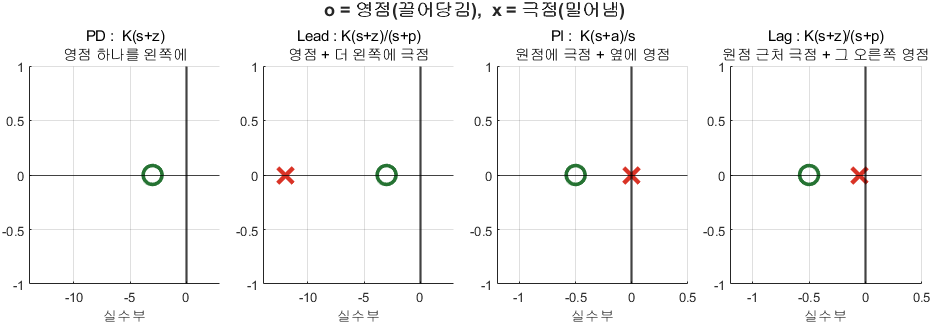

네 보상기가 극점과 영점을 어디에 놓는가

**그림 파일** `w07_pz_map.png` — `make_figures.m` 의 `fig_pz_map` · 다시 만들려면 `make_figures('w07_pz_map')`

**만드는 곳** — `make_figures.m` 의 `fig_pz_map` **직접 확인해 보려면** — `W07_02_pd_and_pi.m` 과 `W07_05_lead_and_lag.m` 에서 각 제어기의 `zpk` 를 찍어 보십시오

그림 해석 — **동그라미는 당기고, 가위표는 밉니다**

마지막 두 줄이 핵심입니다. **PD·Lead 는 빠른 영역(과도응답)을 고치고, PI·Lag 는 느린 영역(정상상태)을 고칩니다.** 서로 간섭하지 않는 이유입니다.

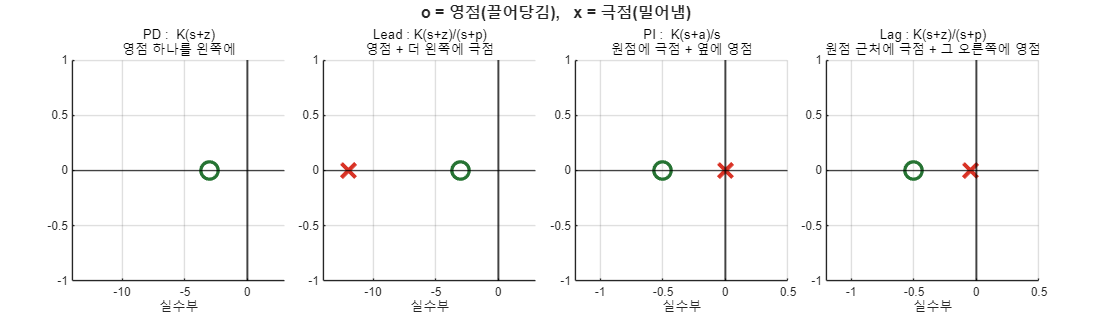

figure('Position',[60 60 1100 320]);
tiledlayout(1,4,'TileSpacing','compact','Padding','compact');
comp = { 'PD :  K(s+z)',            [],        -3,   '영점 하나를 왼쪽에'
         'Lead : K(s+z)/(s+p)',     -12,       -3,   '영점 + 더 왼쪽에 극점'
         'PI :  K(s+a)/s',           0,        -0.5, '원점에 극점 + 옆에 영점'
         'Lag : K(s+z)/(s+p)',      -0.05,     -0.5, '원점 근처에 극점 + 그 오른쪽에 영점' };
for i = 1:4
    nexttile
    hold on; grid on;
    zz = comp{i,3};  pp = comp{i,2};
    plot(zz, 0, 'o', 'MarkerSize', 13, 'LineWidth', 2.5, 'Color', [0.15 0.45 0.2]);
    if ~isempty(pp)
        plot(pp, 0, 'x', 'MarkerSize', 15, 'LineWidth', 3, 'Color', [0.85 0.2 0.15]);
    end
    xline(0, 'k-', 'LineWidth', 1.5);
    yline(0, 'k-');
    if i <= 2, xlim([-14 3]); else, xlim([-1.2 0.5]); end
    ylim([-1 1]);
    xlabel('실수부');
    title(sprintf('%s\n%s', comp{i,1}, comp{i,4}), 'FontSize', 10);
end
sgtitle('o = 영점(끌어당김),   x = 극점(밀어냄)', 'FontSize', 12, 'FontWeight','bold');

그림에서 읽을 것

- **PD 와 Lead** 는 **멀리 왼쪽**에 놓습니다. 과도응답을 고치는 도구입니다

- **PI 와 Lag** 는 **원점 아주 가까이**에 놓습니다. 정상상태 오차를 고치는 도구입니다

- Lead 의 극점은 영점보다 **더 왼쪽**, Lag 의 극점은 영점보다 **더 오른쪽**

왜 이렇게 놓는가

- 과도응답은 **빠른 부분**이 정하므로 멀리 왼쪽을 건드려야 한다

- 정상상태 오차는 **아주 느린 부분**($s \rightarrow 0$)이 정하므로 원점을 건드려야 한다

- 서로 다른 동네를 손보는 것이라 **둘을 같이 써도 방해하지 않습니다** (Lead-Lag)

## 8-2. 네 보상기의 응답을 나란히

같은 플랜트에 넷을 각각 붙여 보면 성격 차이가 바로 보입니다.

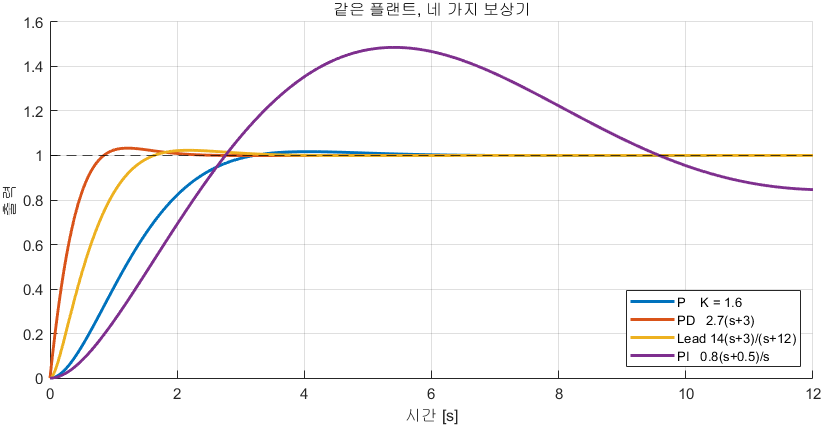

같은 플랜트에 네 보상기를 붙여 보면

**그림 파일** `w07_four_comp.png` — `make_figures.m` 의 `fig_four_comp` · 다시 만들려면 `make_figures('w07_four_comp')`

**만드는 곳** — `make_figures.m` 의 `fig_four_comp` **직접 바꿔 보려면** — 각 제어기의 이득을 바꿔 가며 다시 그려 보십시오. 순위가 쉽게 뒤집힙니다

그림 해석

이 플랜트는 **이미 타입 1** 이라 계단 오차가 원래 없습니다. 그래서 PI 는 도움은 안 되고 느려지기만 했습니다. **문제가 무엇인지 보고 골라야 한다**는 4절의 말이 여기서 확인됩니다.

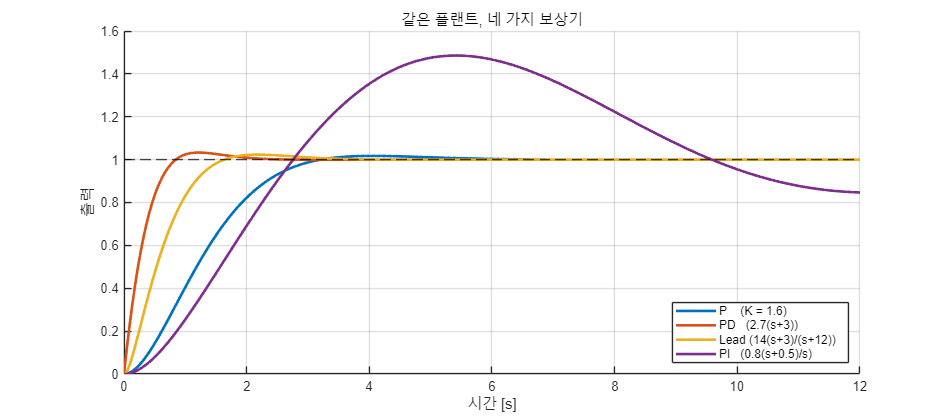

Gc = 1/(s*(s+2));
t8 = (0:0.02:12)';
ctrls = { 'P    (K = 1.6)',            1.6
          'PD   (2.7(s+3))',           2.7*(s+3)
          'Lead (14(s+3)/(s+12))',     14*(s+3)/(s+12)
          'PI   (0.8(s+0.5)/s)',       0.8*(s+0.5)/s };
figure('Position',[60 60 950 420]);
hold on; grid on;
for i = 1:size(ctrls,1)
    Tc = feedback(ctrls{i,2}*Gc, 1);
    if all(real(pole(Tc)) < 0)
        plot(t8, step(Tc, t8), 'LineWidth', 2, 'DisplayName', ctrls{i,1});
    end
end
yline(1, 'k--', 'HandleVisibility','off');
xlabel('시간 [s]'); ylabel('출력'); ylim([0 1.6]);
legend('Location','southeast');
title('같은 플랜트, 네 가지 보상기');

fprintf('=== 네 보상기 비교 (G = 1/(s(s+2))) ===\n');

=== 네 보상기 비교 (G = 1/(s(s+2))) ===


fprintf('  제어기                      오버슈트[%%]  정착시간[s]   오차\n');

  제어기                      오버슈트[%]  정착시간[s]   오차


fprintf('  --------------------------  -----------  -----------  --------\n');

  --------------------------  -----------  -----------  --------


for i = 1:size(ctrls,1)
    Tc = feedback(ctrls{i,2}*Gc, 1);
    ic = stepinfo(Tc);
    fprintf('  %-26s  %11.2f  %11.2f  %8.4f\n', ...
            ctrls{i,1}, ic.Overshoot, ic.SettlingTime, 1-dcgain(Tc));
end

  P    (K = 1.6)                     1.73         2.91    0.0000
  PD   (2.7(s+3))                    3.30         1.66    0.0000
  Lead (14(s+3)/(s+12))              2.33         2.50    0.0000
  PI   (0.8(s+0.5)/s)               48.56        21.80    0.0000


fprintf('\n');

## 9. Simulink 로 확인 — 잡음이 들어오면

모델 `W07_PD_Noise.slx` 는 PD 와 Lead 를 나란히 놓고 **똑같은 측정 잡음**을 넣은 것입니다.

이 모델에는 오늘 처음 보는 블록이 두 개 있습니다. 먼저 그것부터 봅니다.

`Derivative` — 신호를 시간으로 미분하는 블록

- 하는 일 — 들어온 신호 $v(t)$ 를 받아 $\dot{v}(t)$ 를 내보낸다. 전달함수로는 $s$

- 파라미터가 하나도 없다. 더블클릭해 보면 설정할 것이 없다

- 계산 방법 — 지금 값과 바로 앞 스텝의 값의 차이를 스텝 간격으로 나눈다. 즉 $(v_k - v_{k-1})/\Delta t$

- **여기가 문제의 뿌리다.** 잡음은 스텝마다 값이 튀는 신호이므로 분자가 크고, $\Delta t$ 가 작을수록 분모가 작아 결과가 커진다. 솔버가 정밀해질수록(스텝이 작아질수록) 오히려 더 크게 튄다

- 그래서 실무에서는 이 블록을 **거의 쓰지 않는다.** 10절에서 대체품을 만든다

`Band-Limited White Noise` — 정해진 세기의 무작위 신호를 만드는 블록

- 하는 일 — 매 `Sample time` 마다 평균 $0$ 인 난수를 하나 뽑아 내보낸다

- `Noise power` — 잡음의 세기. **분산이 아니라 스펙트럼 밀도**다. 실제 분산은 대략 (Noise power) / (Sample time) 이 된다

- `Sample time` — 얼마나 자주 새 난수를 뽑는지. 실제 센서의 샘플링 주기라고 보면 된다

- `Seed` — 난수의 출발점. **같은 seed 면 매번 똑같은 잡음**이 나온다. 두 제어기를 비교할 때 조건을 똑같이 맞추려면 이것을 고정해야 한다

- 왜 이 블록인가 — 실제 센서 신호에는 늘 잡음이 있다. 시뮬레이션에서 잡음을 빼면 미분기의 문제가 **끝까지 안 보인다**

이제 두 블록을 넣고 돌려 봅니다. 결과가 극적입니다.

잡음이 없을 때

- PD — 오버슈트 $1.0\%$, 최대 제어입력 $56.7\,\mathrm{V}$

- Lead — 오버슈트 $8.2\%$, 최대 제어입력 $265\,\mathrm{V}$

- **둘 다 멀쩡합니다.** 여기까지는 차이가 안 보입니다

아주 작은 잡음을 넣으면

- PD — 최대 제어입력이 $1252\,\mathrm{V}$ 로 폭증. 요동이 $100$ 배

- Lead — $264\,\mathrm{V}$ 로 거의 그대로

**출력(각도)은 둘 다 비슷해 보입니다.** 제어입력만 다릅니다. 그래서 **출력만 보고 판단하면 이 문제를 놓칩니다.**

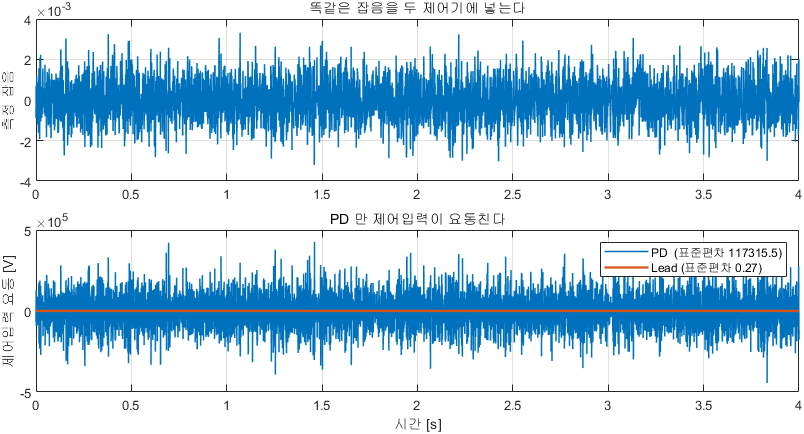

PD 만 제어입력이 요동친다

**그림 파일** `w07_noise.png` — `make_figures.m` 의 `fig_noise` · 다시 만들려면 `make_figures('w07_noise')`

**만드는 곳** — `make_figures.m` 의 `fig_noise` **직접 확인해 보려면** — `W07_06_run_simulink.m` 을 실행하면 `W07_PD_Noise.slx` 로 같은 실험을 합니다

그림 해석 — **위아래 세로축 눈금을 반드시 함께 보십시오**

$117315$ V 를 낼 수 있는 모터 드라이버는 없습니다. 실물에서는 **드라이버가 즉시 포화되고, 곧 고장 납니다.** 시뮬레이션에서 출력만 봤다면 이 문제를 영영 못 봤을 것입니다.

## 9-1. 왜 심각한 문제인가

제어입력이 요동치면 실제로 이런 일이 생깁니다.

- 모터가 떨리고 소음이 난다

- 기어와 베어링이 빨리 마모된다

- 전력 소비가 커지고 드라이버가 발열한다

- 구동기가 계속 포화 근처를 오가며 수명이 준다

이 과목에서 계속 강조하는 것이 이것입니다.

- 6주차 — 제어입력이 구동기 한계를 넘는지 확인하라

- 7주차 — 제어입력이 잡음으로 요동치는지 확인하라

**출력만 보지 말고 제어입력도 보십시오.**

## 9-2. 두 번째 모델 — 포화가 있으면 어떻게 되는가

모델 `W07_Design_Verify.slx` 는 같은 루프를 두 개 갖고 있습니다.

- **위** — 포화 없음. 설계할 때 우리가 가정한 세상

- **아래** — `Saturation` 블록으로 $\pm u_{lim}$ 제한. 실제 세상

4-2 절에서 제어입력 한계까지 넣어 설계한 $K^* = 4.79$ 를 넣고 돌리면

- 두 응답의 최대 차이가 $0$ 이다. 포화가 **한 번도 작동하지 않았다**

- 제어입력 최대치가 $4.79$ 로 한계 $5$ 안에 있기 때문이다

이번에는 이득을 키워 봅니다. 출력 사양만 보고 설계했다면 그렇게 했을 것입니다.

- $K = 10$ — 요구한 입력 $10$, 실제 낸 값 $5$, 출력 차이 $0.31$, 오버슈트 $8.3\%$

- $K = 20$ — 요구한 입력 $20$, 실제 낸 값 $5$, 출력 차이 $0.79$, 오버슈트 $13.9\%$

- $K = 40$ — 요구한 입력 $40$, 실제 낸 값 $5$, 출력 차이 $1.28$, 오버슈트 $15.1\%$

읽는 법

- 요구한 값과 실제 낸 값이 벌어지는 순간부터 응답이 설계와 달라진다

- 오버슈트 $1\%$ 로 설계했는데 실제로는 $15\%$ 가 나온다

- **근궤적은 이 현상을 전혀 모른다.** 포화는 비선형이기 때문이다

그래서 6단계 검증에 제어입력이 반드시 들어가야 합니다.

## 10. 유사미분 — 사실 Lead 와 같은 것

미분항을 안전하게 쓰는 또 하나의 방법이 있습니다.


$$\text{순수 미분} : K_d s \qquad\rightarrow\qquad \text{유사미분} : \frac{K_d s}{\tau s + 1}$$


분모에 1차 필터를 붙인 것입니다. 고주파 이득이 $K_d/\tau$ 로 제한됩니다.

왜 이렇게까지 하는지, 잡음이 조금 섞인 신호를 실제로 미분해 보면 압니다.

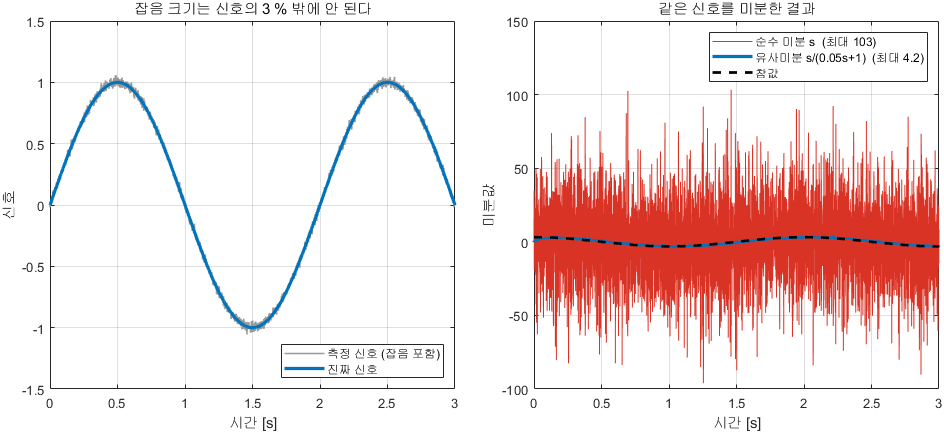

잡음 3 % 가 미분을 지나면 신호를 삼킨다

**그림 파일** `w07_pseudo_deriv.png` — `make_figures.m` 의 `fig_w07_pseudo_deriv` · 다시 만들려면 `make_figures('w07_pseudo_deriv')`

**만드는 곳** — `make_figures.m` 의 `fig_w07_pseudo_deriv` **직접 바꿔 보려면** — 함수 안의 `tau = 0.05` 를 `0.005` 로 줄이면 유사미분도 함께 지저분해집니다

그림 해석

**왼쪽 그림에서는 문제가 안 보이는데 오른쪽에서 터집니다.** 그래서 미분항을 쓸 때는 반드시 제어입력을 그려 봐야 합니다.

그런데 유사미분을 쓴 PD 를 정리해 보면


$$K_p + \frac{K_d s}{\tau s+1} = \frac{(K_p\tau + K_d)s + K_p}{\tau s + 1}$$


분자와 분모가 모두 1차인 전달함수, 즉 **Lead 입니다.** 이름만 다를 뿐 같은 것을 하고 있는 셈입니다.

Simulink 의 `PID Controller` 블록도 내부적으로 이 방식을 씁니다. 블록을 열면 "Filter coefficient N" 이라는 값이 있는데 그것이 $\tau = 1/N$ 입니다. 11주차에서 다시 만납니다.

## 11. 오늘의 정리

**설계 절차**

- **설계 6단계** : 사양 → $s$ 평면 → 궤적 → 영역 → 이득 → **검증**

- 5단계까지는 근사식이다. 6단계의 `stepinfo` 실측이 진짜 답이다

- `rl_scan` 으로 이득을 훑고 `ctrl_input` 으로 제어입력을 확인한다

**비례제어로 안 되는 세 가지 경우**

- 궤적이 사양 영역을 비껴간다 (6주차의 DC 모터)

- 궤적이 실축을 벗어나지 않아 진동 사양 자체가 성립하지 않는다 (예제 B)

- 오차 사양이 요구하는 이득이 안정 한계를 넘는다 (예제 C)

**설계할 때 조심할 것**

- **감쇠비만 보고 오버슈트를 판단하지 말 것.** 영점이 가까우면 어긋난다

- 안정한 극점 상쇄는 써도 되지만 **불안정한 극점 상쇄는 절대 금지**

- 제어입력을 사양에 넣으면 답이 좁아지고 고르는 기준이 생긴다

- 손 공식 : 비례제어는 $u(0^+) = K$. PD 는 **상대차수에 따라 갈린다** — $r=2$ 면 $K(z-Kb)$, $r\ge3$ 이면 $Kz$ (4-2-1절)

**보상기**

- 근궤적이 사양 영역을 비껴가면 **길 자체를 바꿔야** 한다

- **PD** 는 영점을 추가해 궤적을 왼쪽으로 당긴다. 과도응답을 고친다

- 영점 위치는 감이 아니라 **각도 부족**으로 계산한다 : 목표 극점에서 $-180^\circ$ 에 모자란 각 $\phi$ 를 재고 $z = \sigma_d + \omega_d/\tan\phi$ 에 놓는다 (2-0절)

- 그렇게 해도 **오버슈트는 공식보다 커진다.** 영점이 더 키우기 때문이다. 목표를 보수적으로 잡고 되풀이한다

- **PI** 는 원점 극점을 추가해 타입을 올린다. 정상상태 오차를 고친다

- 둘은 서로 다른 문제를 풀며 **서로를 대신할 수 없다**

- PD 는 부적절해서 **실제로 만들 수 없다.** MATLAB 도 거부한다

- **Lead** 는 PD 에 극점을 붙여 고친 것. $p$ 를 $z$ 의 $5\sim20$ 배로

- **Lag** 는 PI 의 원점 극점을 원점 근처로 옮겨 안전하게 만든 것

- Lead 와 Lag 는 식이 같고 부등호만 다르다

- $p$ 를 키우면 성능은 좋아지지만 제어입력이 커진다. **맞바꿈이다**

- 잡음이 들어오면 PD 의 제어입력만 요동친다. **출력만 보면 놓친다**

## 12. 다음 주 예고

8주차는 **중간고사**입니다. 범위는 1~7주차입니다.

9주차부터는 같은 문제를 **주파수영역**에서 다시 봅니다.

- 오늘 "고주파 이득" 이라고 부른 것이 **Bode 선도**로 정확히 그려집니다

- "위상을 앞서게 한다" 는 Lead 의 이름 뜻도 그때 이해하게 됩니다

- 그리고 안정도를 "얼마나 여유가 있는가" 로 재는 법을 배웁니다

근궤적과 주파수응답은 같은 것을 다른 각도에서 보는 두 도구입니다. 둘 다 할 줄 알아야 실무에서 상황에 맞게 골라 쓸 수 있습니다.